## **Driver test program to check Clothoids library**

**Test G2 clothoid**

close all;

% G2 fitting data
x0     = -1;
y0     = 0;
theta0 = pi*0.9;
kappa0 = 0.2 + 1e-10;

x1     = 1;
y1     = 0;
theta1 = -pi*1.001;
kappa1 = 0.2 + 0;

figure('Position',[1,1,800,500]);
subplot(2,2,[1,3]);

% compute G2 clothoid

S = ClothoidList();
iter = S.build_3arcG2(x0,y0,theta0,kappa0,x1,y1,theta1,kappa1);
iter

iter = int64
   3


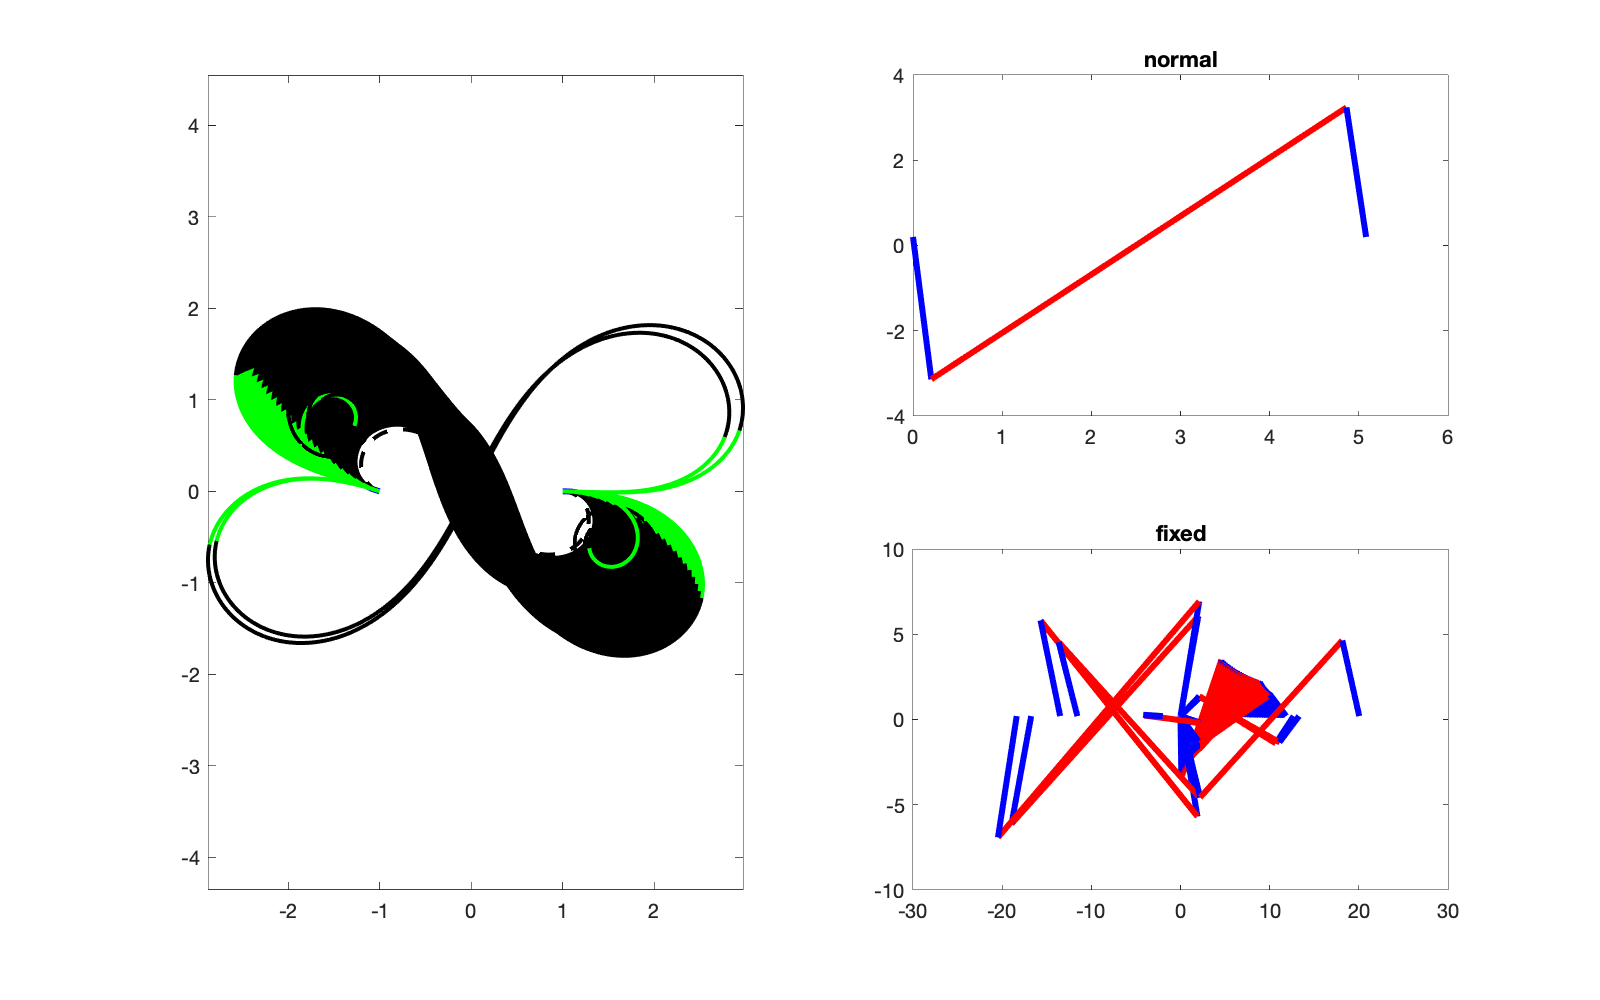

computed = 4.5%


computed = 9.1%


computed = 14%


computed = 18%


computed = 23%


computed = 27%


computed = 32%


computed = 36%


computed = 41%


computed = 45%


computed = 50%


computed = 55%


computed = 59%


computed = 64%


computed = 68%


computed = 73%


computed = 77%


computed = 82%


computed = 86%


computed = 91%


computed = 95%


computed = 1e+02%


if iter > 0
  S.plot();
end
axis equal;
hold on;

SG = ClothoidCurve();
SG.build_G1(x0,y0,theta0,x1,y1,theta1);
SG.plot(1000,'--k','Linewidth',2);

SS = ClothoidList();

X = 0.1:0.1:2.2;
Y = 0.1:0.1:2.2;
Z = zeros(length(X),length(Y));
L = zeros(length(X),length(Y));
K = zeros(length(X),length(Y));
i = 0;
imax = Inf;
imin = 0;
iave = 0;
ntot = 0;
for s0=X
  i = i+1;
  fprintf('computed = %.2g%%\n',100*i/length(X));
  j = 0;
  for s1=Y
    j = j+1;
    iter = SS.build_3arcG2fixed(...
      s0,x0,y0,theta0,kappa0,...
      s1,x1,y1,theta1,kappa1 ...
    );
    SS0 = SS.get(1);
    SS1 = SS.get(2);
    SS2 = SS.get(3);

    [ ~, ~, kappa ] = SS.getSTK();
    Z(i,j) = NaN;

    iave = iave + iter;
    ntot = ntot + 1;
    imax = max(imax,iter);
    imin = min(imin,iter);
    if iter > 0 && SS0.length() > 0 && SS1.length() > 0 && SS2.length() > 0
      Z(i,j) = sum(sum(abs([SS0.dkappa(),SS1.dkappa(),SS2.dkappa()])));
      K(i,j) = max(max(abs(kappa)));
      L(i,j) = SS0.length() + SS1.length() + SS2.length();
      %disp('pippo')
      subplot(2,2,[1,3]);
      hold on
      fmt1 = {'Color','green','LineWidth',2};
      fmt2 = {'Color','black','LineWidth',2};
      fmt3 = {'Color','green','LineWidth',2};
      try
        SS0.plot(100,fmt1{:});
        SS1.plot(100,fmt2{:});
        SS2.plot(100,fmt3{:});
      catch
        warning('Skip plot');
      end
    end
    
    iave = iave/ntot;

    subplot(2,2,2);
    S.plotCurvature(1000);
    title('normal');

    subplot(2,2,4);
    SS.plotCurvature(1000);
    title('fixed');

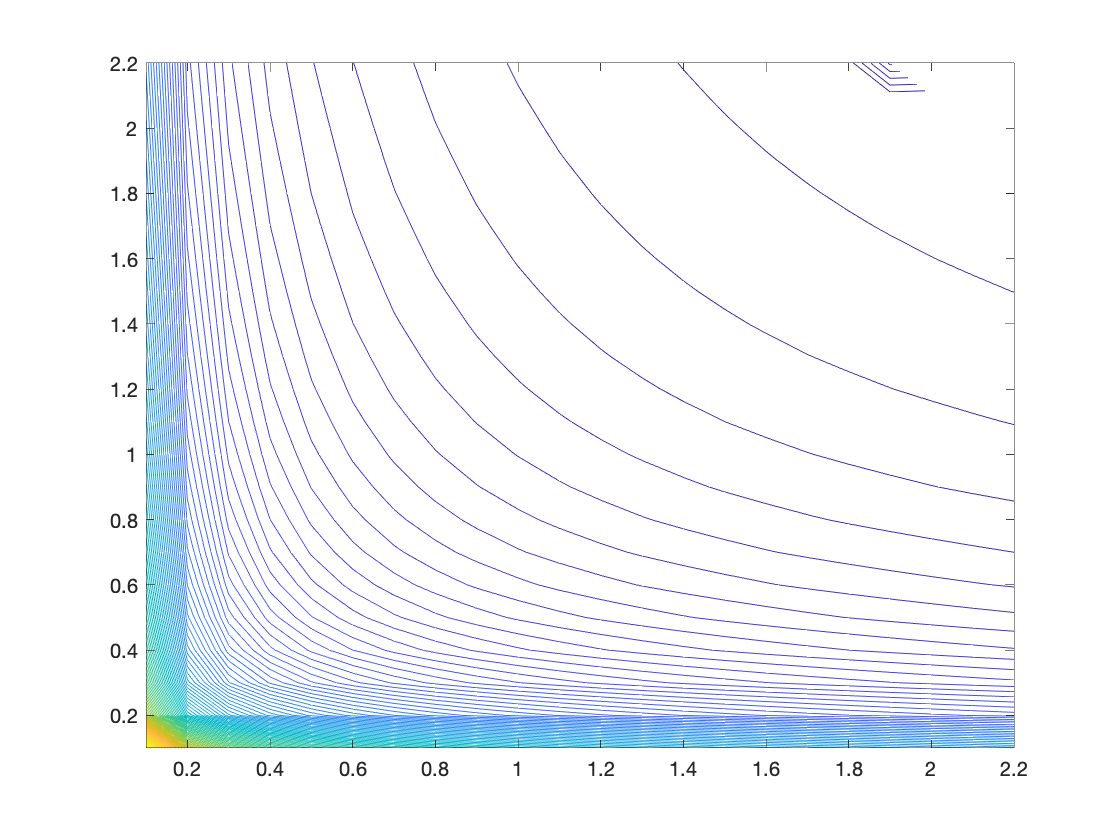

iave = 0, imin = 0, imax = 9223372036854775807


  end
end

figure();
contour(X,Y,Z,100);

fprintf('iave = %g, imin = %d, imax = %d\n',iave, imin, imax );
